## Exercice : Fastcore & Fastcormics on a Toy Model 

*Author : Hugues Escoffier *

clear
initCobraToolbox();
changeCobraSolver('gurobi');

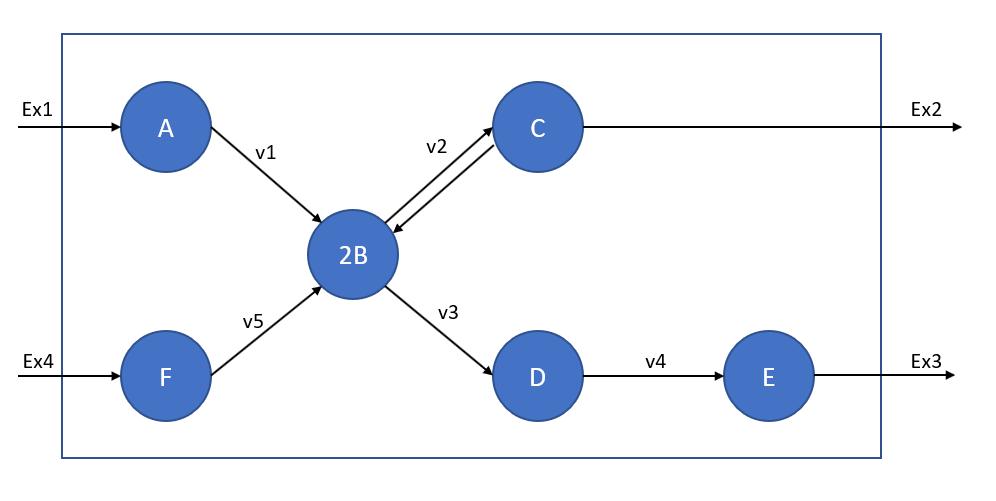

#### Question 1 : Create the model using the createModel function 

% Create model


Add the following description to your model : b

model.description = 'recon'

#### Question 2 : Is the model consistent ? 

% Enter your code here


#### Question 3: 

- 1. Find and print the exchange reactions that are importing these metabolites from the cell into the model.

% Enter your code here


 In this exercice, we want the model to be able to exchange only with the metabolites present in the medium. 

medium = {'A[c]'}

- 2. Find the reactions that are open in the model regarding the medium  

% Enter your code here


- 3. Based on the results of the previous questions, find exchanges reactions that should be unable to carry a flux and save them in a variable.

% Enter your code here


- 4. Block reactions from carrying a flux by changing the corresponding bound to 0. Then run FASTCC again on the medium constrained model. 

% Enter your code here


- 5. Run FASTCC to obtain again a medium constrained model:

% Enter your code here


#### **Question 4: **

in this part we want to mazimize the Ex3 reaction. 

- 1. Find the index for the Ex3 reaction 

% Enter your code here


- 2. Change objective 

% Enter your code here


- 3. Optimize the model to maximize the objective of the model

% Enter your code here


#### Question 5: 

- **Core reactions : v1, v3 **

Add core reactions : 

- 1. Using Fastcore

list_core_reactions = {'v1', 'v3'};

In order to run fastcore, you need a list of core reaction indexes. 

                    a. Create a list containing the cores reactions indexes (v1 and v3)

% Enter your code here


                    b. Run the fastcore() function 

**fastcore() **

Input :

- **model** : S - *m x 1* Stoichiometric matrix * lb - *n x 1* Lower bounds * ub - *n x 1* Upper bounds * rxns - *n x 1* cell array of reaction abbreviations

- **core** : Indices of reactions in cobra model that are part of the core set of reactions

- *epsilon : Smallest flux value that is considered nonzero (default 1e-4)*

- *printLevel : 0 = silent, 1 = summary, 2 = debug (default - 0)*

- *adaptiveScalingFlag : 0 = adaptive scaling is off (default), 1 = adaptive scaling is on (recommended for ill scaled models)*

- *nonPen : list of reactions whose addition to the model is not be penalized*

Output: 

- **tissueModel** : extracted model

- *coreRxnBool : n x 1 boolean vector indicating core reactions*

More informations : [https://opencobra.github.io/cobratoolbox/stable/modules/dataIntegration/transcriptomics/FASTCORE/index.html](https://opencobra.github.io/cobratoolbox/stable/modules/dataIntegration/transcriptomics/FASTCORE/index.html) 

% Enter your code here


- 2. Using Fastcormics

For fastcormircs, unlike fastcore requires a matrix in which each gene is associated with a number: 

- 0 if unknown

- 1 if expressed (core reaction)

- -1 if not expressed (inactive)

% Optional settings 
optionalSettings = struct;
optionalSettings.func = {'Ex3'};
% optionalSettings.medium = {};
% optionalSettings.notMediumConstrained = {};

rownames = medium_constrained_consistent_model.genes; % Change according to the name of your model
dico = table(medium_constrained_consistent_model.genes, medium_constrained_consistent_model.genes); % Change according to the name of your model
biomassReactionName = 'Ex3'; 
consensusProportion = 1;
epsilon = 1e-4;
fillingMediumFlag = 0;

                    a. Create a discretize matrix based on the core reactions 

% Enter your code here


                    b. Run fastcormics_RNAseq function 

**rFastcormics4cobra_v2(model, discretized, rownames, dico)**

- **model **: Model use to extract the context-specific model from.

- **discretized** : Matrix with *n* rows (1 per gene) and *m* columns (1 per sample) with 1 for expressed genes, 0 for unknown expression and -1 for unexpressed genes. 

- **rownames** : Cell array with the gene IDs (as many rows as the number of genes in `discretized`).

- **dico** :  Table with two columns, first for gene IDs in the `model` format, second for gene IDs in the `discretized` format.

**Optional inputs**

- **consensusProportion **: The rate of samples that have to express or not to express a gene for the gene to be considered expressed or not (default 0.9).

- **epsilon** : Smallest flux value that is considered nonzero (default 1e-4).

- **optionalSettings.func** : Cell array of reaction abbreviations that should carry a flux. It is recommended to put the objective function of your model to ensure its preservation in the context-specific model.

- **optionalSettings.medium** : Cell array of metabolite abbreviations that are present in the growth medium of the cells and that will be used to constrain the model.

- **optionalSettings.notMediumConstrained : **Reactions not included in the medium that must be retained.

- **biomassReactionName **: String or character array with the name of the objective/biomass reaction (default 'biomass_reaction').

- **fillingMediumFlag** : Fill the medium with supplementary reactions in case the provided medium is not sufficient to fulfill the objective function. 1 for active (default), 0 for inactive.

- **adaptiveScalingFlag** : Adaptive scaling of the flux values. 0 for inactive (default), 1 for active.

**Outputs**

- **contextSpecificModel** : Context-specific model, reduced to the retained reactions and associated genes.

- **retainedRxns** : Indices in `model` of the retained reactions.

- **indicesCompletedCoreOrig** : Indices in `model` of the core reactions.

The complete documentation of rFastcormics_v2 can be found on github : [rFASTCORMICS/rFASTCORMICS for RNA-seq data/rFASTCORMICS_v2 at master · sysbiolux/rFASTCORMICS](https://github.com/sysbiolux/rFASTCORMICS/tree/master/rFASTCORMICS%20for%20RNA-seq%20data/rFASTCORMICS_v2).

% Enter your code here


                    c. Visualize the model 

% Enter your code here
